# **Gol'dberg representation**

**2023-03-27**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

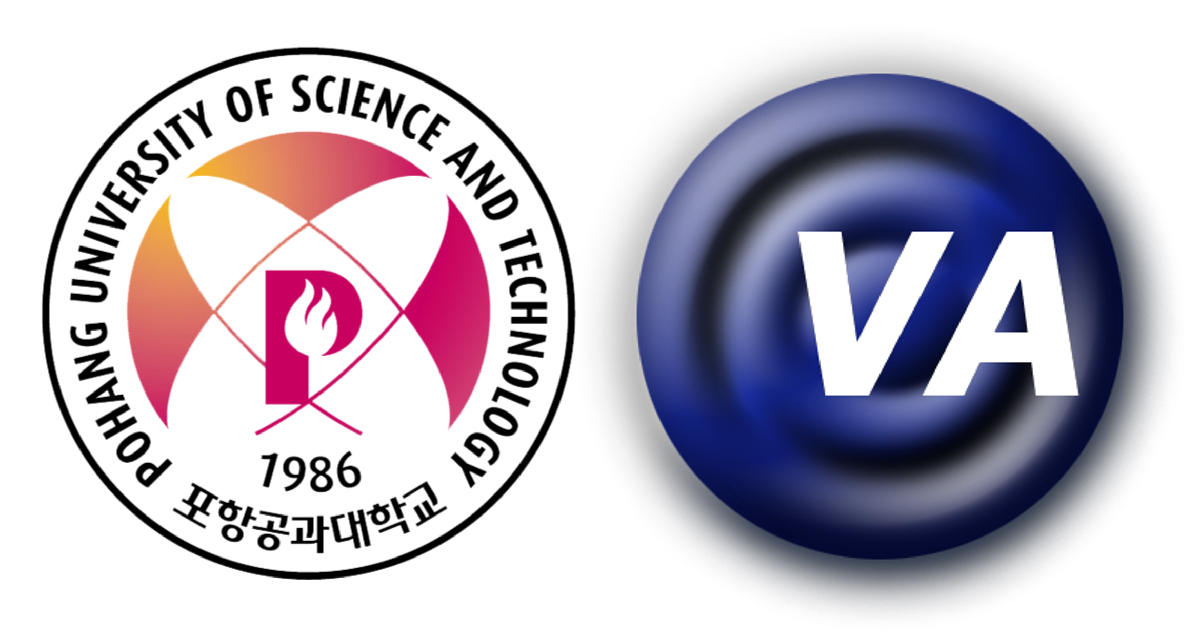

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

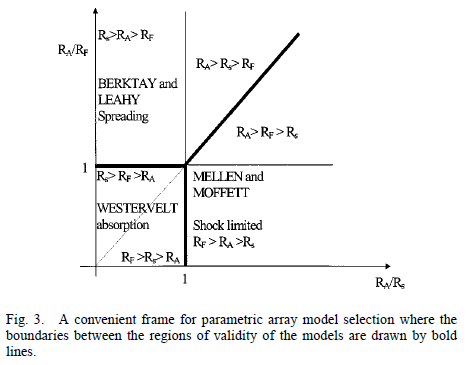

## Reference

- Kopp, L., et al. (2000). "Potential performance of parametric communications." IEEE Journal of Oceanic Engineering 25(3): 282-295.

###     Absorption limited model

- Westervelt, P. J. (1963). "Parametric Acoustic Array." The Journal of the Acoustical Society of America 35(4): 535-537.

###     Spreading limited Model

- Berktay, H. O. and D. J. Leahy (1974). "Farfield performance of parametric transmitters." The Journal of the Acoustical Society of America 55(3): 539-546.

###     Shock-wave limtied model

- Moffett, M. B. and R. H. Mellen (1977). "Model for parametric acoustic sources." The Journal of the Acoustical Society of America 61(2): 325-337.

## 3 basic distances which control the behavior of the parametric array

- Absorption length:                 $R_{A}=L_{a}=\frac{1}{\alpha\left(f_{p}\right)}$

- Rayleigh distnace:                 $R_{F}=z_{0}
=\frac{1}{2}ka^{2}
=\frac{\pi a^{2}}{\lambda_{p}}
=\frac{\pi a^{2}f_p}{c_{0}}$

- Shock formation distance:    $R_{S}=\bar{x}
=\frac{1}{\beta \varepsilon k_{p}}
=\frac{c_0}{2\pi \beta \varepsilon f_p}
=\frac{c_0^{2}}{2\pi \beta u_p f_p}$

## 3 basic modeling options

- Absorption limited

- Westervelt's initial model

- Design parameter:    $f_{p}$

- Spreading limited

- Berktay and Leahy

- Design parameter:    $f_{p}$, $a$

- Shock-wave limtied

- Mellen and Moffett

- Design parameter:    $f_{p}$, $a$, $u_{p}$

## Gol'dberg representation

- Gol'dberg number:                                                    $X=\Gamma=\frac{R_A}{R_S}=\frac{\beta \varepsilon k_{p}}{\alpha_p}
=\frac{2\pi \beta u_p f_p}{c_0^{2} \alpha \left(f_p \right)}$

- A properly normalized inverse Rayleigh distance:    $Y=\frac{R_A}{R_F}=\frac{\lambda_p}{\alpha_p \pi a^2}

=\frac{c_{0}}{\pi a^{2}f_p \alpha \left( f_p \right)}$

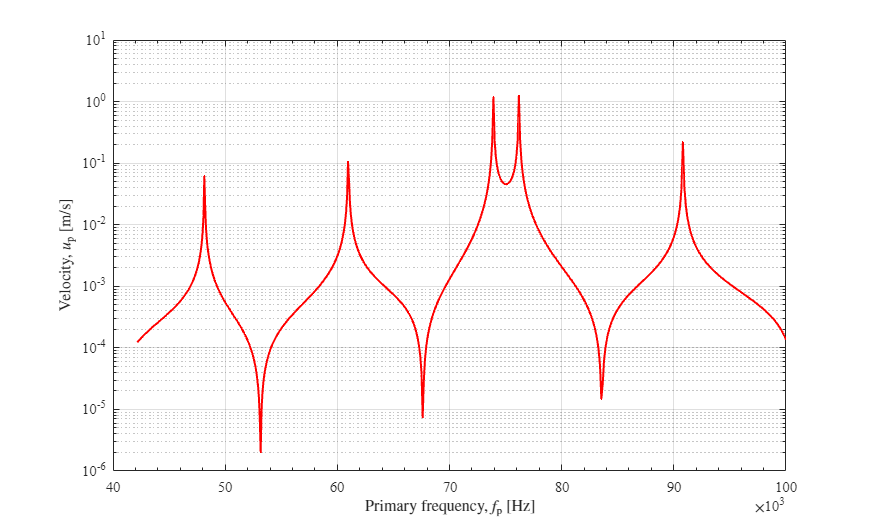

clear

air = importfile_air('air.txt');

% a0 = 10e-3:10e-3:50e-3;
a0 = 50e-3;

fr_comsol = importfile_COMSOL_fr('230406 -Langevin, stepped-horn and plate.txt');
freq_p = fr_comsol.freq(1001:end)';
u_pt = fr_comsol.v(1001:end)'/10;

u_pn = 5;
u_p = logspace(-2,0,u_pn);
u_p = u_p'*ones(length(freq_p),1)';

alpha = air_absorption(freq_p,20,20,1)/8.686;
% High-frequency asymptotic absorption
% alpha = 1.84e-11*freq_p.^2;

createfigure_xy_multi(freq_p,u_pt, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',18,9);

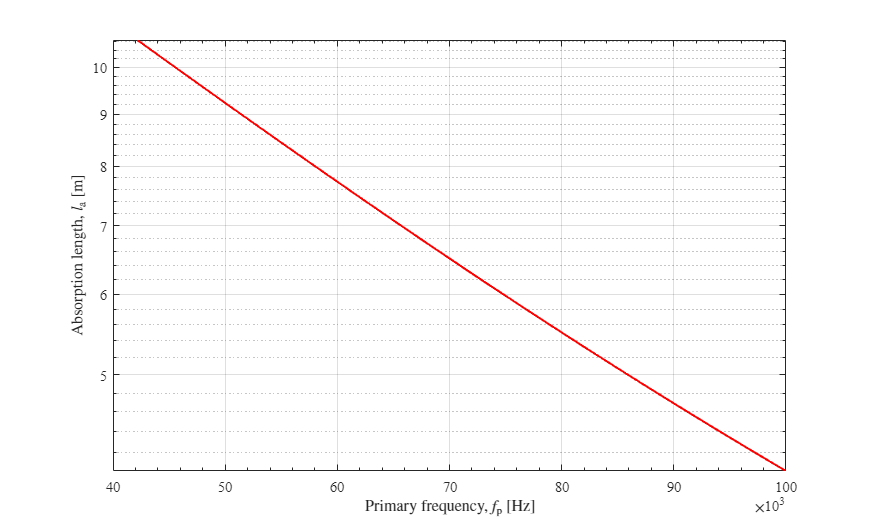


% Absorption length
l_alpha = 1./alpha;
createfigure_xy_multi(freq_p,l_alpha, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Absorption length, $l_\mathrm{a}$ [m]', ...
    'linear','log','centimeters',18,9);

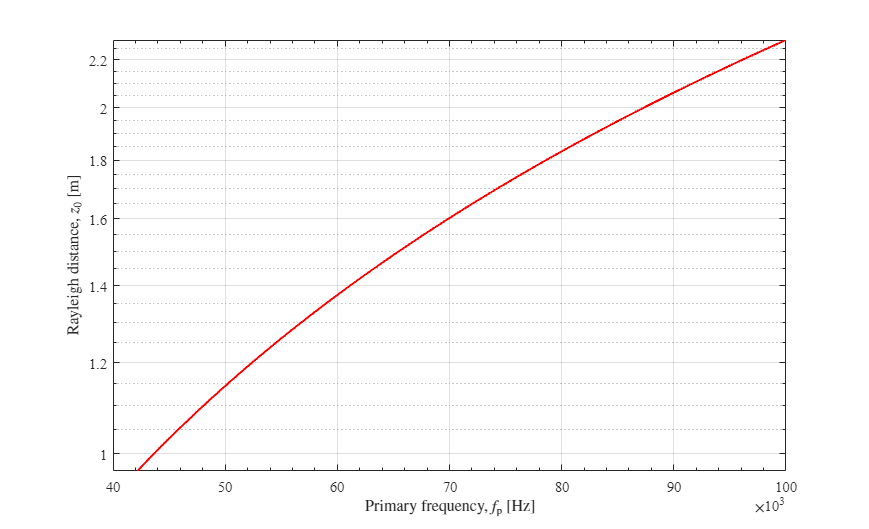


% Rayleigh distance
z0 = pi*a0'.^2*freq_p/air.c0;
createfigure_xy_multi(freq_p,z0, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Rayleigh distance, $z_0$ [m]', ...
    'linear','log','centimeters',18,9);

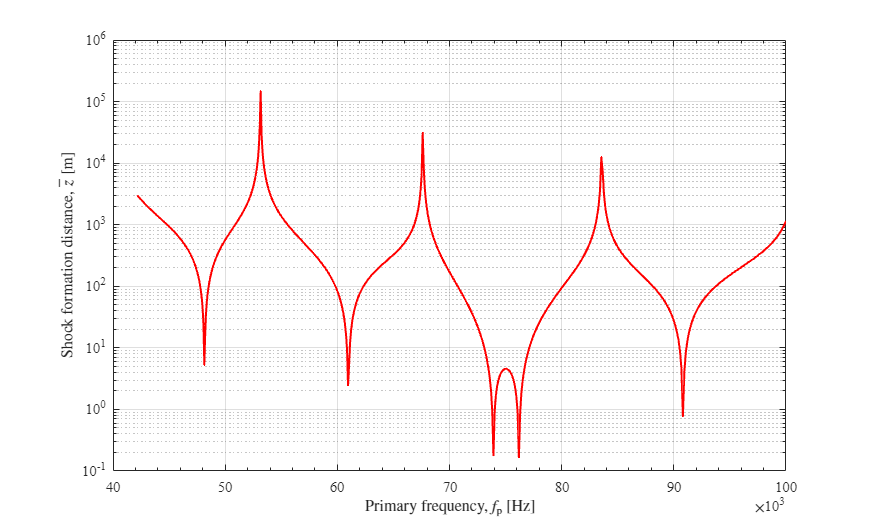


% Shock formation distance
z_t = air.c0^2./(2*pi*air.beta*u_pt.*freq_p);
z_ = air.c0^2./(2*pi*air.beta*u_p.*freq_p);
createfigure_xy_multi(freq_p,z_t, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Shock formation distance, $\bar{z}$ [m]', ...
    'linear','log','centimeters',18,9)

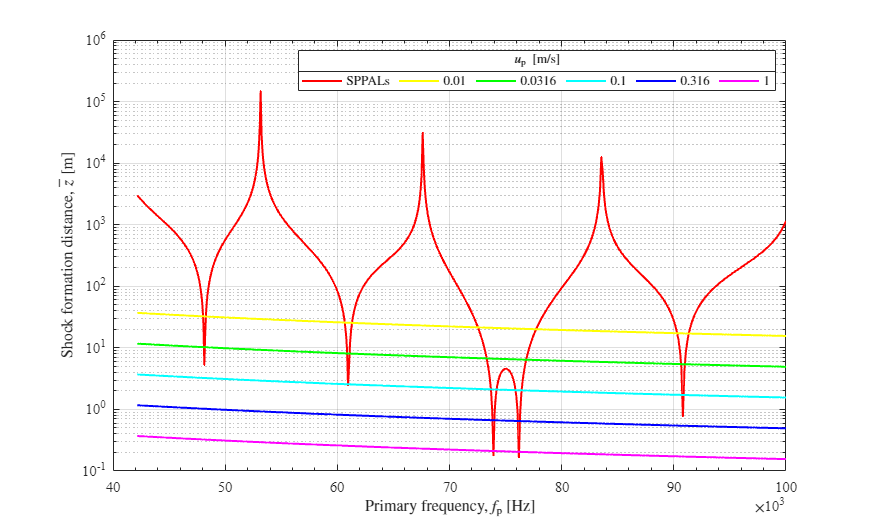

createfigure_xy_multi(freq_p,[z_t; z_], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Shock formation distance, $\bar{z}$ [m]', ...
    'linear','log','centimeters',18,9,'$u_\mathrm{p} \ \left[ \mathrm{m}/\mathrm{s} \right]$',['SPPALs'; compose("%.3g",u_p(:,1))],6)

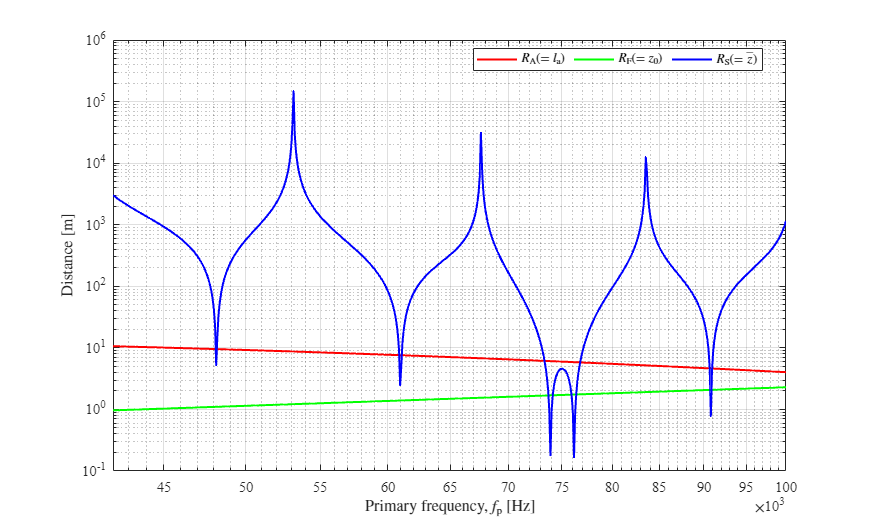


createfigure_xy_multi(freq_p,[l_alpha; z0; z_t], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Distance [m]', ...
    'log','log','centimeters',18,9,'',["$R_\mathrm{A} \left(=l_\mathrm{a}\right)$" "$R_\mathrm{F} \left(=z_0\right)$" "$R_\mathrm{S} \left(=\bar{z}\right)$"],3)

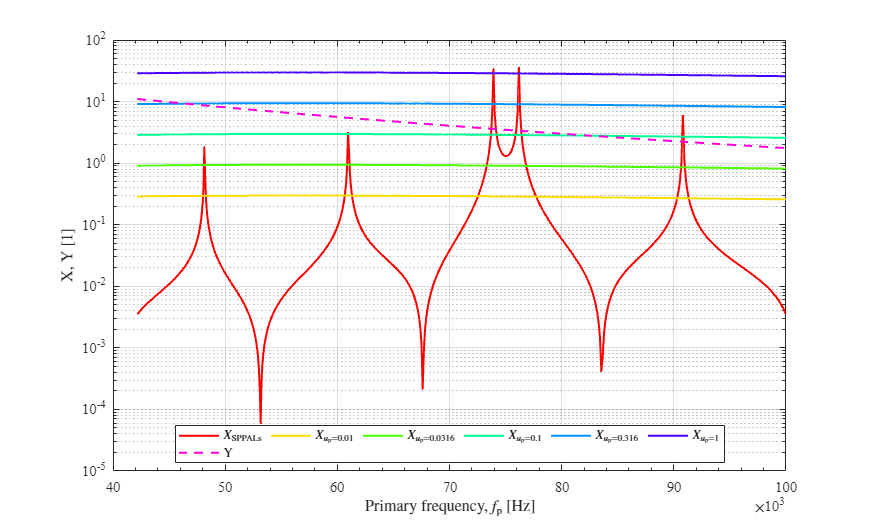


Xt = l_alpha./z_t;
X = repmat(l_alpha,u_pn,1)./z_;

Y = l_alpha./z0;

createfigure_xy_multi(freq_p,[Xt; X; Y], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','X, Y [1]', ...
    'linear','log','centimeters',18,9,'',["$X_{\mathrm{SPPALs}}$" compose("$X_{u_\\mathrm{p}=%.3g}$",u_p(:,1)') "Y"], 6)

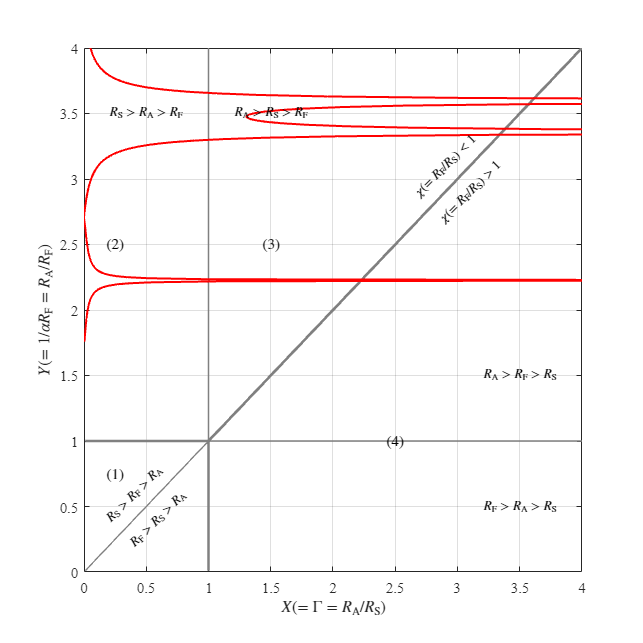


createfigure_goldberg(Xt, Y, 'linear')

- Small-signal absorption limiting in the collimated zone

- Absorption limiting in the far spherical zone

- Saturation limiting in the far spherical zone (but small-signal absorption limits the array length)

- Saturation limiting in the collimated zone

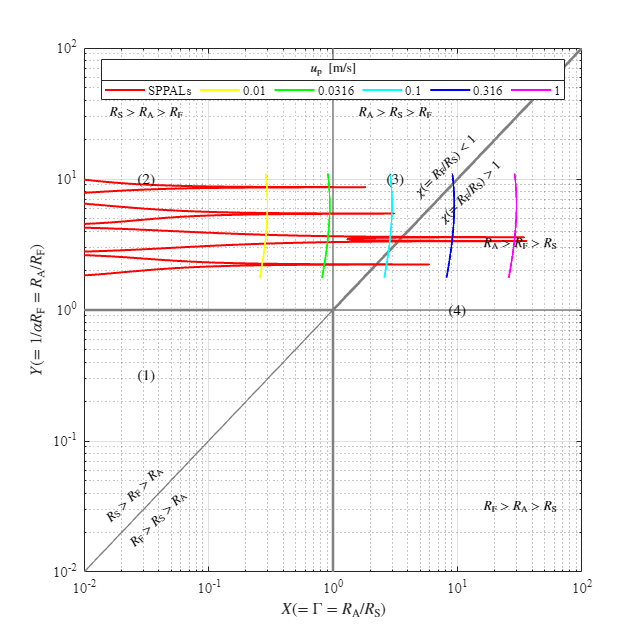

createfigure_goldberg([Xt; X], Y, 'log', '$u_\mathrm{p} \ \left[ \mathrm{m}/\mathrm{s} \right]$',['SPPALs'; compose("%.3g",u_p(:,1))])

- Small-signal absorption limiting in the collimated zone

- Absorption limiting in the far spherical zone

- Saturation limiting in the far spherical zone (but small-signal absorption limits the array length)

- Saturation limiting in the collimated zone

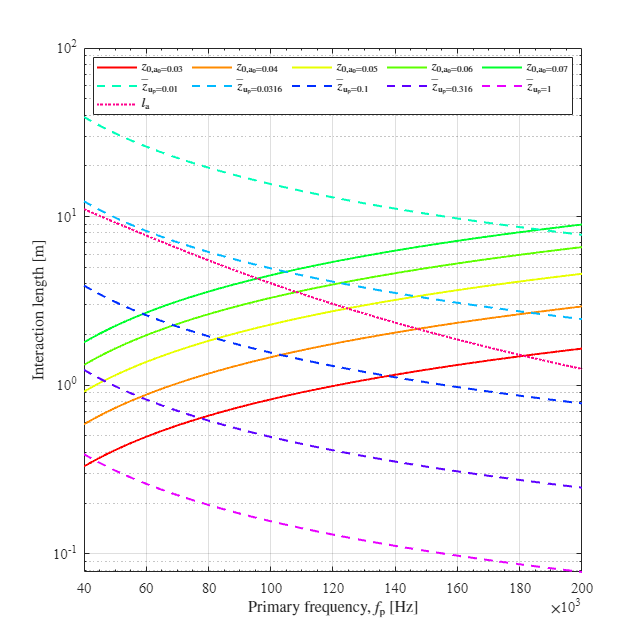

a0 = 30e-3:10e-3:70e-3;

freq_p = linspace(40e3, 200e3, 601);

alpha = air_absorption(freq_p,20,20,1)/8.686;

% Absorption length
l_alpha = 1./alpha;
% Rayleigh distance
z0 = pi*a0'.^2*freq_p/air.c0;
% Shock formation distance
u_pn = 5;
u_p = logspace(-2,0,u_pn);
u_p = u_p'*ones(length(freq_p),1)';
z_ = air.c0^2./(2*pi*air.beta*u_p.*freq_p);

createfigure_xy_multi(freq_p,[z0; z_; l_alpha], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Interaction length [m]', ...
    'linear','log','centimeters',12,12,'',[compose("$z_{0, \\mathrm{a_0}=%.3g}$",a0) compose("$\\bar{z}_{\\mathrm{u_p}=%.3g}$",u_p(:,1)') '$l_\mathrm{a}$'], 5)

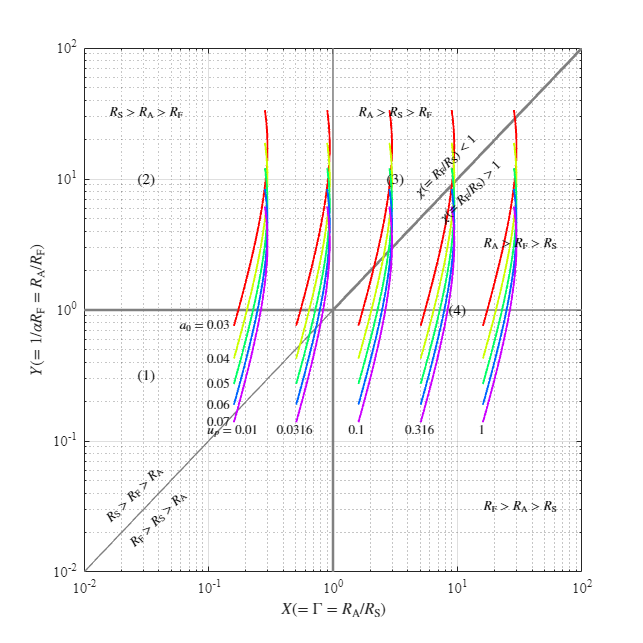

X = repmat(l_alpha./z_,[1 1 size(z0,1)]);
X = permute(X, [1 3 2]);
Y = repmat(l_alpha./z0,[1 1 size(z_,1)]);
Y = permute(Y, [3 1 2]);
createfigure_goldberg_multi(X, Y, 'log', u_p(:,1), a0)

## KZK parabolic wave equation


$$\frac{\partial^2p}{\partial z \partial \tau}
- \frac{c_0}{2} \nabla_\perp^2 p
- \frac{\delta}{2 c_0^3} \frac{\partial^3 p}{\partial \tau^3}
=
\frac{\beta}{2 \rho_0c_0^3} \frac{\partial^2 p^2}{\partial \tau^2}$$


###     Assumption regarding the source

- The source is defined in the plane, $z=0$.

- The source has a characteristic radius, $a$.

- The source radiates at frequencies that satisfy the relation, $ka \gg 1$.

The last assumption ensures that the beam is reaonably directional.

Because of the assumed directionality of the beam, the sound is localized in the vincinty of the $z$ axis, and the wavefronts are quasi-planar.

###     High frequency limit on the parabolic approxiamation

It is necessary to consider the $\mathcal{O} \left( \varepsilon^2 \right)$ in $\nabla^2$.

## Quasilinear KZK solution for the difference frequency


$$p_{-} \left(r,z,\tau \right) =
\frac{1}{2j} q_{-} \left(r,z \right) e^{j\omega_{-} \tau} + \mathrm{c.c.}$$


where


$$q_{-} \left(r,z \right) \cong
\frac{-j p_{0a} p_{0b} \beta k_{-}^2 a^2}
{4 \rho_0 c_0^2 \alpha_{T}}
\frac{e^{-\alpha_{-}z}}{z}
D_{W} \left(\theta \right) D_{A} \left(\theta \right)
\exp{ \left( -\frac{1}{2} j k_{-} z \tan^2{\theta} \right)}$$



$$\bar{z}=\frac{1}{\beta \varepsilon k}
=\frac{1}{\beta} \frac{\rho c_0^2}{p_0} \frac{c_0}{2\pi f_0}
=\frac{\rho c_0^3}{2\pi f_0 \beta p_0}$$



$$p_0=\frac{\rho c_0^3}{2\pi f_0 \beta \bar{z}}$$



$$k_-^2=\left( \frac{2 \pi f_-}{c_0} \right)^2
=\frac{4\pi^2 f_a^2}{c_0^2}\left( \frac{f_{-}}{f_{a}} \right)^2$$



$$z_0 = \frac{1}{2}k_aa^2
= \frac{\pi f_a}{c_0} a^2$$



$$a^2 = \frac{z_0 c_0}{\pi f_a}$$



$$\alpha_-
=\frac{1}{l_{a-}}
=\frac{1}{l_{aa}} \left( \frac{l_{aa}}{l_{a-}} \right)
=\frac{1}{l_{aa}} \left( \frac{f_{-}}{f_{a}} \right)^2$$



$$z=\xi z_0$$



$$\alpha_T
=\alpha_a+\alpha_b-\alpha_-
=\frac{1}{l_{aa}}+\frac{1}{l_{ab}}-\frac{1}{l_{a-}}
=\frac{1}{l_{aa}} \left( 1 +\frac{l_{aa}}{l_{ab}}-\frac{l_{aa}}{l_{a-}} \right)
=\frac{1}{l_{aa}} \left( 1 + \left( \frac{f_{b}}{f_{a}} \right)^2 - \left( \frac{f_{-}}{f_{a}} \right)^2 \right)
=\frac{1}{l_{aa}} \left( 1 + \left( \frac{f_{a}-f_{-}}{f_{a}} \right)^2 - \left( \frac{f_{-}}{f_{a}} \right)^2 \right)
=\frac{1}{l_{aa}} \left( 1 + \left( 1-\frac{f_{-}}{f_{a}} \right)^2 - \left( \frac{f_{-}}{f_{a}} \right)^2 \right)
=\frac{2}{l_{aa}} \left( 1 - \frac{f_{-}}{f_{a}} \right)$$


when $\theta=0$,


$$q_{-} \left(z \right) \cong
\frac{-j p_{0a} p_{0b} \beta k_{-}^2 a^2}
{2 \rho_0 c_0^2 \alpha_{T}}
\frac{e^{-\alpha_{-}z}}{z}$$


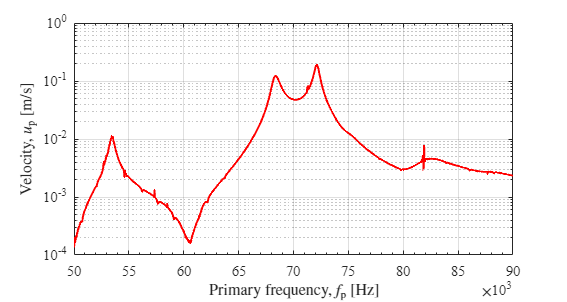

f_a = 72.2e3;
a   = 50e-3;
% a   = 25e-3;
z   = 1;

% Define the velocity response of the transducer
% u_a = 0.0316;
% f_t = linspace(40e3, 200e3, 601);
% % u_t = u_a*ones(1,length(f_t));
% u_t = f_t;

% by COMSOL Multiphysics, 230406 -Langevin, stepped-horn and plate.mph
% f_t = fr_comsol.freq(1001:end)';
% u_t = fr_comsol.v(1001:end)'/10;

% from KCY, kcy - freq vs. measured vel (velocity.xlsx)
fr_kcy_m = importfile_fr('kcy - freq vs. measured vel (velocity.xlsx).txt');
f_t = fr_kcy_m.freq';
% u_t = fr_kcy_m.res';
u_t = fr_kcy_m.res'*0.3;

% from KCY, kcy - diff freq vs. SPL (DFW_SPL_1m.xlsx)
fr_kcy_m    = importfile_fr('kcy - diff freq vs. SPL (DFW_SPL_1m.xlsx).txt');
f_diff_e    = fr_kcy_m.freq';
spl_diff_e  = fr_kcy_m.res';

createfigure_xy_multi(f_t,u_t, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',10,3);

% Interpolating the veclocity response of the transudcer
u_tq = @(f_tq) interp1(f_t, u_t, f_tq);

q_ = @(f_a, f_diff, a, z) (air.rho^2*air.c0^2*u_tq(f_a)*u_tq(f_a-f_diff)*air.beta*(2*pi*f_diff/air.c0)^2*a^2)...
    /(4*air.rho*air.c0^2*2*1.84e-11*f_a*(f_a-f_diff))...
    *exp(-1.84e-11*f_diff^2*z)/z;

l_a = @(f_a) 1/(1.84e-11*f_a.^2);
l_a(f_a)

ans = 10.4258

z_ = @(u_0a, f_a) (air.c0^2)/(air.beta*2*pi*f_a*u_0a);
z_(u_tq(f_a), f_a)

ans = 1.1958


$$X=\frac{l_{aa}}{\bar{z}_a}
=\frac{\beta \varepsilon_a k_a}{\alpha_a}
=\frac{\beta u_a 2 \pi f_a}{1.84 \times 10^{-11}f_a^2 c_0^2}
=\frac{2 \pi \beta u_a}{1.84 \times 10^{-11}f_a c_0^2}$$


x_ = @(u_0a, f_a) (air.beta*2*pi*u_0a)...
    /(1.84e-11*f_a*air.c0^2);


$$Y=\frac{l_{aa}}{z_{0a}}
=\frac{1}{\alpha_a \frac{1}{2}k_aa^2}
=\frac{1}{1.84 \times 10^{-11}f_a^2 \frac{1}{2}k_a a^2}
=\frac{c_0}{1.84 \times 10^{-11}f_a^2 \pi f_a a^2}
=\frac{c_0}{1.84 \times 10^{-11} \pi a^2 f_a^3}$$


y_ = @(f_a, a) air.c0...
    /(1.84e-11*f_a^3*pi*a^2);

% Test
% q_(200e3, 1e3, 50e-3, 1)
% x_(0.0316, 200e3)
% y_(200e3, 50e-3)

x_(u_tq(f_a), f_a)

ans = 8.7189

y_(f_a, a)

ans = 6.3063

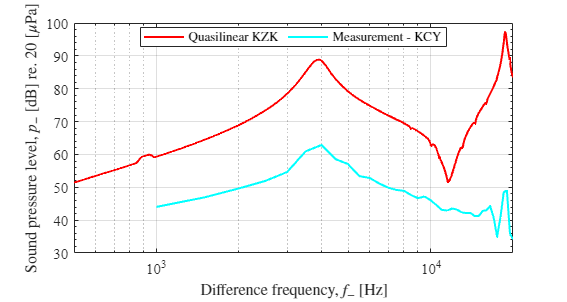


f_n = 1001;
f_diff  = logspace(log10(500),log10(2e4),f_n);
q   = zeros(1,f_n);
for i=1:f_n
    q(i) = q_(f_a, f_diff(i), a, z);
end

createfigure_xy_multi_sep([f_diff f_diff_e],[20*log10(q/20e-6) spl_diff_e],[numel(f_diff) numel(f_diff_e)],...
    'Difference frequency, $f_{-}$ [Hz]','Sound pressure level, $p_{-}$ [dB] re. 20 $[\mu \mathrm{Pa}]$', ...
    'log','linear','centimeters',10,3,'',["Quasilinear KZK" "Measurement - KCY"],2);

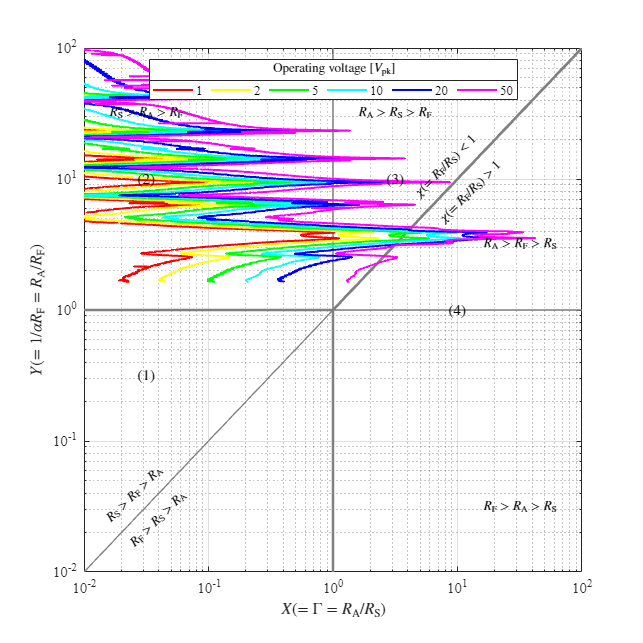

% from kcy - freq vs. measured vel (234021)
kcy_m_230421.a0 = 51.8e-3;
kcy_m_230421.fr_kcy_m_230421 = importfile_fr('kcy - freq vs. measured vel (234021).txt',6);
kcy_m_230421.fr_kcy_m_230421 = table2array(kcy_m_230421.fr_kcy_m_230421);

kcy_m_230421.freq_p = kcy_m_230421.fr_kcy_m_230421(:,1);
kcy_m_230421.u_pt   = kcy_m_230421.fr_kcy_m_230421(:,2:7);

% find the index of maxima
kcy_m_230421.u_pt_peak = kcy_m_230421.u_pt(islocalmax(kcy_m_230421.u_pt(:,1),'MaxNumExtrema',2));
kcy_m_230421.peak_idx(1) = find(kcy_m_230421.u_pt(:,1)==kcy_m_230421.u_pt_peak(1));
kcy_m_230421.peak_idx(2) = find(kcy_m_230421.u_pt(:,1)==kcy_m_230421.u_pt_peak(2));

% Absorption length
kcy_m_230421.alpha = air_absorption(kcy_m_230421.freq_p,20,20,1)/8.686;
kcy_m_230421.l_alpha = 1./kcy_m_230421.alpha;
% Rayleigh distance
kcy_m_230421.z0 = pi*kcy_m_230421.a0.^2*kcy_m_230421.freq_p/air.c0;
% Shock formation distance
kcy_m_230421.z_t = air.c0^2./(2*pi*air.beta*kcy_m_230421.u_pt.*kcy_m_230421.freq_p);

kcy_m_230421.X = repmat(kcy_m_230421.l_alpha./kcy_m_230421.z_t, 1);
kcy_m_230421.Y = repmat(kcy_m_230421.l_alpha./kcy_m_230421.z0, [1 6]);
createfigure_goldberg(kcy_m_230421.X, kcy_m_230421.Y, 'log','Operating voltage $\left[ V_{\mathrm{pk}} \right]$',["1" "2" "5" "10" "20" "50"],2);

% % Absorption length
% kcy_m_230421.l_alpha(kcy_m_230421.peak_idx)
% % Rayleigh distance
% kcy_m_230421.z0(kcy_m_230421.peak_idx)
% % Shock formation distance
% kcy_m_230421.z_t(kcy_m_230421.peak_idx,:)
% kcy_m_230421.X(kcy_m_230421.peak_idx,:)
% kcy_m_230421.Y(kcy_m_230421.peak_idx,:)
kcy_m_230421.bl_peak = ...
    table(kcy_m_230421.freq_p(kcy_m_230421.peak_idx),...
    kcy_m_230421.l_alpha(kcy_m_230421.peak_idx),...
    kcy_m_230421.z0(kcy_m_230421.peak_idx),...
    kcy_m_230421.z_t(kcy_m_230421.peak_idx,:),...
    'VariableNames',["freq_peak" "l_a" "z_0" "z_"]);
kcy_m_230421.bl_peak = splitvars(kcy_m_230421.bl_peak, ...
    'z_','NewVariableNames',{'z_01' 'z_02' 'z_05' 'z_10' 'z_20' 'z_50'});
disp(kcy_m_230421.bl_peak)

    freq_peak     l_a       z_0       z_01      z_02      z_05      z_10      z_20       z_50  
    _________    ______    ______    ______    ______    ______    ______    _______    _______

      68978      6.6155    1.6952    6.4315    3.1697    1.2895    0.6891    0.38662    0.20061
      72317      6.2511    1.7773     5.578    2.6992     1.066    0.5903    0.32542    0.18539



kcy_m_230421.gol_peak = ...
    table(kcy_m_230421.freq_p(kcy_m_230421.peak_idx),...
    kcy_m_230421.X(kcy_m_230421.peak_idx,:),...
    kcy_m_230421.Y(kcy_m_230421.peak_idx)',...
    'VariableNames',["freq_peak" "X" "Y"]);
kcy_m_230421.gol_peak = splitvars(kcy_m_230421.gol_peak, ...
    'X','NewVariableNames',{'X_01' 'X_02' 'X_05' 'X_10' 'X_20' 'X_50'});
disp(kcy_m_230421.gol_peak)

    freq_peak     X_01      X_02      X_05      X_10      X_20      X_50       Y   
    _________    ______    ______    ______    ______    ______    ______    ______

      68978      1.0286    2.0871    5.1301    9.6001    17.111    32.976    3.9024
      72317      1.1207    2.3159    5.8639     10.59    19.209    33.719    3.5173



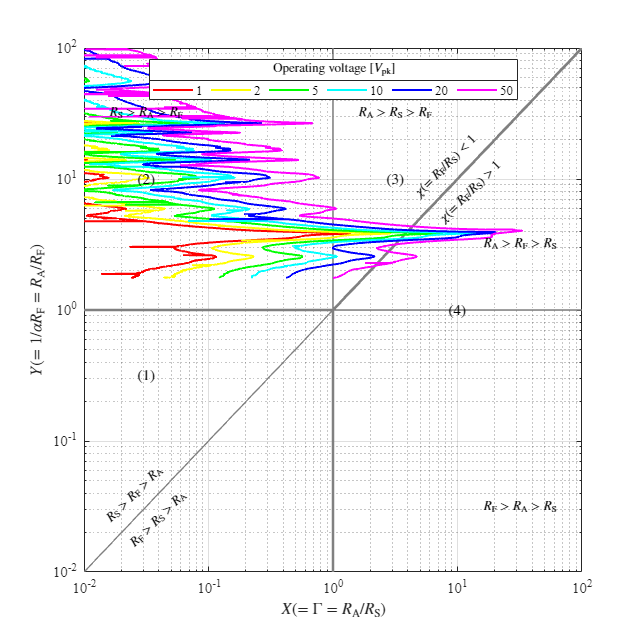

% from obs - freq vs. measured vel (234021)
obs_m_230421.a0 = 50e-3;
obs_m_230421.fr_obs_m_230421 = importfile_fr('obs - freq vs. measured vel (234021).txt',6);
obs_m_230421.fr_obs_m_230421 = table2array(obs_m_230421.fr_obs_m_230421);

obs_m_230421.freq_p = obs_m_230421.fr_obs_m_230421(:,1);
obs_m_230421.u_pt   = obs_m_230421.fr_obs_m_230421(:,2:7);

% find the index of maxima
obs_m_230421.u_pt_peak = obs_m_230421.u_pt(islocalmax(obs_m_230421.u_pt(:,1),'MaxNumExtrema',2));
obs_m_230421.peak_idx(1) = find(obs_m_230421.u_pt(:,1)==obs_m_230421.u_pt_peak(1));
obs_m_230421.peak_idx(2) = find(obs_m_230421.u_pt(:,1)==obs_m_230421.u_pt_peak(2));

% Absorption length
obs_m_230421.alpha = air_absorption(obs_m_230421.freq_p,20,20,1)/8.686;
obs_m_230421.l_alpha = 1./obs_m_230421.alpha;
% Rayleigh distance
obs_m_230421.z0 = pi*obs_m_230421.a0.^2*obs_m_230421.freq_p/air.c0;
% Shock formation distance
obs_m_230421.z_t = air.c0^2./(2*pi*air.beta*obs_m_230421.u_pt.*obs_m_230421.freq_p);

obs_m_230421.X = repmat(obs_m_230421.l_alpha./obs_m_230421.z_t, 1);
obs_m_230421.Y = repmat(obs_m_230421.l_alpha./obs_m_230421.z0, [1 6]);
createfigure_goldberg(obs_m_230421.X, obs_m_230421.Y, 'log','Operating voltage $\left[ V_{\mathrm{pk}} \right]$',["1" "2" "5" "10" "20" "50"],2);

% % Absorption length
% obs_m_230421.l_alpha(obs_m_230421.peak_idx)
% % Rayleigh distance
% obs_m_230421.z0(obs_m_230421.peak_idx)
% % Shock formation distance
% obs_m_230421.z_t(obs_m_230421.peak_idx,:)
% obs_m_230421.X(obs_m_230421.peak_idx,:)
% obs_m_230421.Y(obs_m_230421.peak_idx,:)
obs_m_230421.bl_peak = ...
    table(obs_m_230421.freq_p(obs_m_230421.peak_idx),...
    obs_m_230421.l_alpha(obs_m_230421.peak_idx),...
    obs_m_230421.z0(obs_m_230421.peak_idx),...
    obs_m_230421.z_t(obs_m_230421.peak_idx,:),...
    'VariableNames',["freq_peak" "l_a" "z_0" "z_"]);
obs_m_230421.bl_peak = splitvars(obs_m_230421.bl_peak, ...
    'z_','NewVariableNames',{'z_01' 'z_02' 'z_05' 'z_10' 'z_20' 'z_50'});
disp(obs_m_230421.bl_peak)

    freq_peak     l_a       z_0       z_01      z_02      z_05       z_10       z_20       z_50  
    _________    ______    ______    ______    ______    _______    _______    _______    _______

      71749      6.3113    1.6429    4.5984    2.1928    0.86037    0.52607    0.36941    0.30349
      86002      4.9943    1.9693    43.371    21.791      8.795     4.7512     2.3682     1.0684



obs_m_230421.gol_peak = ...
    table(obs_m_230421.freq_p(obs_m_230421.peak_idx),...
    obs_m_230421.X(obs_m_230421.peak_idx,:),...
    obs_m_230421.Y(obs_m_230421.peak_idx)',...
    'VariableNames',["freq_peak" "X" "Y"]);
obs_m_230421.gol_peak = splitvars(obs_m_230421.gol_peak, ...
    'X','NewVariableNames',{'X_01' 'X_02' 'X_05' 'X_10' 'X_20' 'X_50'});
disp(obs_m_230421.gol_peak)

    freq_peak     X_01       X_02      X_05       X_10      X_20      X_50       Y   
    _________    _______    ______    _______    ______    ______    ______    ______

      71749       1.3725    2.8782     7.3356    11.997    17.085    20.796    3.8415
      86002      0.11515    0.2292    0.56786    1.0512    2.1089    4.6747    2.5362

